# 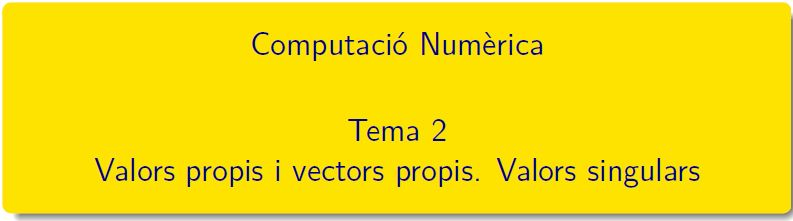

============================================================================

# TEMA 2. ÀLGEBRA LINEAL NUMÈRICA

`Document preparat per M. Àngela Grau Gotés, 13 de març de 2023`

## 2.2 Valors i vectors propis d'una matriu. Mètode de la potència.

### Part I . Propietats geomètriques

#### **Idea: Av tendeix al vector propi de valor propi màxim**

clearvars;
A = [1.8,0.8; 0.2,1.2]
[Veps,Vaps] = eig(A)
save dades.mat A Veps Vaps

% Mòdul màxim
v = Veps(:,1);  y = [-0.5;1]
kmax=8; llista = zeros(size(2,kmax));
llista = y/norm(y);
for k = 2:kmax  
    y= A*y;
    llista = [llista,k*y/norm(y)];
end
% Gràfica
U = llista(1,:); V = llista(2,:);
n=k+1;
compass(n*v(1),n*v(2),'r')
hold on
compass(U,V)
hold off

#### Idea: inv(A)v tendeix al vector propi de valor propi mínim

clearvars; 
load dades.mat
% Mòdul mínim
v = Veps(:,2); y = [0.5;1]
kmax=8; llista = zeros(size(2,kmax))
llista = y/norm(y);
for k = 2:kmax  
    y= A\y;
    llista = [llista,k*y/norm(y)];
end
% Gràfica
U = llista(1,:); V = llista(2,:);
n=k+1;
compass(n*v(1),n*v(2),'r')
hold on
compass(U,V)
hold off

#### Fites dels valors propis. 

Un dels resultats més elementals és el que ens relaciona el mòoul dels valors propis d'una matriu amb la norma de la matriu; recordem-lo:

- Teorema. Si  $\lambda$ és un valor propi de la matriu A; llavors, $|\lambda| \leq ||A||$

clf, clearvars
% A = [2 2 2; 2 4 1; 1 1 10]
%A = [1 0 10; 2 3 1; 1 1 1]/10
A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


fites = [norm(A),norm(A,1),norm(A,'inf'),norm(A,'fro')]  % vap <=||A||

fites =     4.6995    5.0000    7.0000    5.0000


- Cercles de Gershgoring

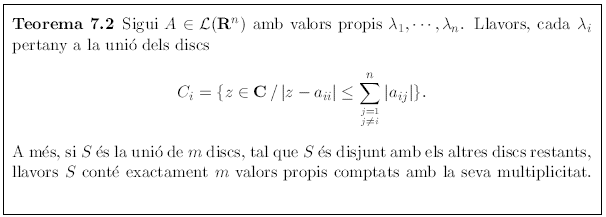

Vàlid per files o per columnes

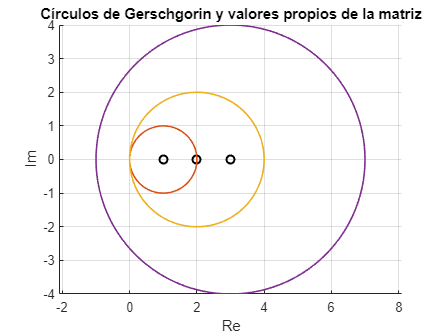

C = Gershgoring(A);   % |z-a(i,i)| <= sum(|a(i,:)|)-|a(i,i)|

### Part II. Jocs de proves

#### Exemple 1. Mètode de la potència per al valor propi de mòdul més gran

Calculeu, amb quatre xifres significatives, el valor propi dominant de la matriu:       $A=\left (\begin{array}{rrr}
1 & 0 & -1 \\
1 & 2 & 1 \\
2 & 2 & 3
\end{array} \right)$  

Proveu amb $x^0_{max}=\left (\begin{array}{r} 0 \\ 0\\ 1 \end{array} \right)\,,\quad   x^0_{min}=\left (\begin{array}{r} 1 \\ -1\\ 1 \end{array} \right)\$

A = [1 0 -1; 1 2 1; 2 2 3]


#### Exemple 2. Mètode de la potència per al valor propi de mòdul més petit

#### Exemple 3. Afegim el criteri del quocient de Rayleigh 

function C = Gershgoring(A)
%% Se dibujan los círculos de Gerschgorin de la matriz A.
    [m n] = size(A);
    d = diag(A); cx = real(d); cy = imag(d);
    B = A - diag(d);
    r = sum(abs(B')); % Suma filas de A sin diagonal
    C = [cx cy r(:)];
    t = 0:pi/100:2*pi; c = cos(t); s = sin(t);
    [v d] = eig(A); % eig calcula los valores propios de A
    d = diag(d); % En d valores propios
    u1 = real(d); v1 = imag(d);
    hold on, grid on, axis equal
    xlabel('Re'), ylabel('Im')
    h1_line = plot(u1,v1,'ok');
    set(h1_line,'LineWidth',1.5)
    for i=1:n % Se dibujan los círculos de Gerscgorin
        x = zeros(1,length(t)); y = zeros(1,length(t));
        x = cx(i)+r(i)*c; y = cy(i)+r(i)*s;
        h2_line = plot(x,y);
        set(h2_line,'LineWidth',1.2)
    end
    hold off
    title('Círculos de Gerschgorin y valores propios de la matriz')
end
%------------------------------------------------------------------

`Document preparat per M. Àngela Grau Gotés, 13 de març de 2023`